# RESULT: Arm Shape Comparison

*MATLAB Version: '23.2.0.2409890 (R2023b) Update 3'*

*Last revised: 8/17/2024*

*Authors: Bill Fan*

This document should contain all that is necessary for the RESULTS subsection on applying the attainability methods for comparing different overall arm shapes for reaching a specific tip pose and load configuration.

First, we will define a target task, which comprises of a target tip pose and tip load. For this example we will approximate a drawer-opening task.

%% Step 1: Define target trajectory keybpoints
% Base pose: hanging down
pose_base = [0; 0; -pi/2];

% Keypoint poses: [x y theta]
pose_1 = [0.3; -0.4; 0];
pose_2 = [0.2; -0.4; 0];
pose_3 = [0.1; -0.4; 0];

poses = [pose_1];

% Create load vector
qx = 5; % Load of opening the drawer: 1N
Q = [qx; 0; 0]; % If we move to the left to open the drawer, then the drawer force will pull to the right

% Step 2: For each pose, find a shearless base-curve which reaches the goal point and minimizes certain desired metrics:
N_segs = 5;                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                        
cost_func = @base_curve_cost_std_of_all_ls;
%cost_func = @base_curve_cost_sum_of_dists_from_target_squared;
%cost_func = @(mat_geom)base_curve_cost_sum_of_std_from_each_segment(mat_geom);
cell_g_circ = find_base_curve_use_heuristics(pose_base, poses, Q, N_segs, cost_func);


Solver stopped prematurely.

fmincon stopped because it exceeded the function evaluation limit,
options.MaxFunctionEvaluations = 3.000000e+03.



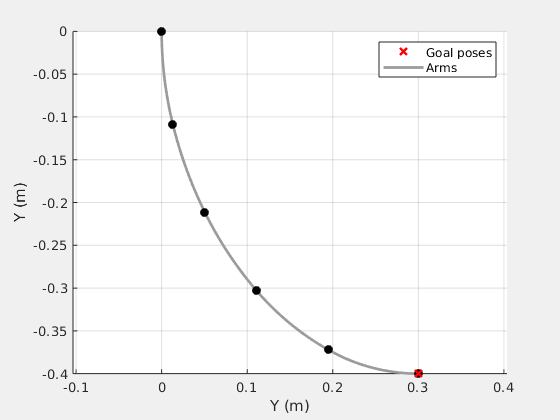


ax = axes(figure("Visible", true));
hold on
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2)
notch_points = zeros(3, size(poses, 2) * N_segs);

i_count = 1;
for i_pose = 1 : size(poses, 2)
    % For each tip pose, plot the arm that is reaching it
    pose_i = Pose2.hat(pose_base);
    mat_g_circ_out_i = cell_g_circ{i_pose};

    notch_points_i = zeros(3, N_segs + 1);
    for i = 1 : N_segs
        % For each segment along the way, save a notch-point denoting the
        % ends of the segment, as well as plot the rod for the segment itself
        rod_i = RodSegment(Pose2, 1, pose_i);
        rod_i.g_circ_right = mat_g_circ_out_i(:, i);
        Plotter2D.plot_rod(rod_i, ax);
    
        pose_i = pose_i * Twist2.expm(mat_g_circ_out_i(:, i));
        notch_points_i(:, i+1) = Pose2.vee(pose_i);
    end
    plot(notch_points_i(1, :), notch_points_i(2, :), 'ok', "markerfacecolor", "k");
end
plot(poses(1, :), poses(2, :), 'rx', "MarkerSize", 7, "Linewidth", 2)

legend(["Goal poses", "Arms"])

grid on
xlabel("Y (m)")
ylabel("Y (m)")

function v_cost = base_curve_cost_v(v_in)
    % Formulate cost term as the variance of the lengths
    mat_g_circ_right  = v_geom_to_g_circ(v_in);

    lengths = mat_g_circ_right(1, :);
    v_cost = std(lengths);
end

% Kinematic base curve costs
function cost = base_curve_cost_sum_of_var_from_each_arm(mat_geom)
    % Note: This seems to reproduce the results of individually
    % minimizing each arm
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    v_stds = zeros(length(cell_g_circ_right), 1);
    
    for i = 1 : length(cell_g_circ_right)
        lengths_i = cell_g_circ_right{i}(1, :);
        v_stds(i) = std(lengths_i);
    end
    cost = sum(v_stds);
end

function cost = base_curve_cost_sum_of_std_from_each_segment(mat_geom)
    % Note: This seems to reproduce the results of individually
    % minimizing each arm
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    v_stds = zeros(length(cell_g_circ_right), 1);
    
    mat_g_circ_right = cat(3, cell_g_circ_right{:});

    for i = 1 : length(cell_g_circ_right)
        v_stds(i) = std(mat_g_circ_right(1, i, :));
    end
    cost = sum(v_stds);
end

function cost = base_curve_cost_sum_of_dists_from_target_squared(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);

    target_l = 0.17;
    dist_from_target_l = all_ls - 0.17;
    cost = sum(100 * dist_from_target_l.^4);
end

function cost = base_curve_cost_norm_of_stds(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    v_cost = zeros(length(cell_g_circ_right), 1);
    
    for i = 1 : length(cell_g_circ_right)
        lengths_i = cell_g_circ_right{i}(1, :);
        v_cost(i) = std(lengths_i) + norm(lengths_i);
    end

    cost = norm(v_cost);
end

function cost = base_curve_cost_std_of_all_ls(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);
    all_curvatures = all_twists(3, :);

    indiv_costs = [std(all_ls); norm(all_ls); norm(all_curvatures)];
    w = [1; 1; 0.1];
    cost = dot(w, indiv_costs);
end

function cost = base_curve_cost_std_dist_from_target_l(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);

    target_l = 0.17;
    dist_from_target_l = abs(all_ls - 0.17);
    cost = norm(dist_from_target_l);
end

% Mechanics-based base-curve costs
function cost = base_curve_cost_min_shear_force(mat_geom)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    
    cell_g_ucirc_left = cell(size(cell_g_circ_right));
    for i = 1 : length(cell_g_circ_right)
        simple_arm.g_circ_right = cell_g_circ_right{i};
        cell_g_ucirc_left{i} = simple_arm.calc_external_reaction(tip_load);
    end
    all_g_ucircs = [cell_g_ucirc_left{:}];
    all_shears = all_g_ucircs(2, :);
    cost = norm(all_shears);
end

function cost = base_curve_cost_min_bending_moment(mat_geom, tip_load, N_segs)
    cell_g_circ_right = mat_geom_to_g_circ(mat_geom);
    
    simple_arm = ArmSeriesFactory.constant_2d_muscle_arm(N_segs, 0.01, 1);
    
    cell_g_ucirc_left = cell(size(cell_g_circ_right));
    for i = 1 : length(cell_g_circ_right)
        simple_arm.g_circ_right = cell_g_circ_right{i};
        cell_g_ucirc_left{i} = simple_arm.calc_external_reaction(tip_load);
    end
    all_g_ucircs = [cell_g_ucirc_left{:}];
    all_moments = all_g_ucircs(3, :);
    cost_bending_moment = norm(all_moments);

    all_twists = [cell_g_circ_right{:}];
    all_ls = all_twists(1, :);

    dist_from_target_l = abs(all_ls - 0.15);
    cost_l_dist_to_target = norm(dist_from_target_l);

    cost = cost_bending_moment + cost_l_dist_to_target;
end

function mat_g_circ_right = v_geom_to_g_circ(v_geom)
    % Convert a "geometry vector" to a matrix of twists
    % By "geometry vector" I mean [l_1; k_1; l_2; k_2; ...; l_n; k_n]
    n_g_circ = length(v_geom)/2;
    mat_l_k = reshape(v_geom, [2, n_g_circ]);
    lengths = mat_l_k(1, :);        % lengths
    shears = zeros(1, n_g_circ);    % shears
    curvatures = mat_l_k(2, :);     % curvatures

    mat_g_circ_right = [lengths; shears; curvatures];
end

function cell_g_circ_out = mat_geom_to_g_circ(mat_geom)
    % Convert a "geometry matrix" to a cell array of matrices of twists
    
    N_poses = size(mat_geom, 2);
    N_segs = size(mat_geom, 1) / 2;
    cell_g_circ_out = cell(1, N_poses);
    for i = 1 : N_poses
        v_geom_i = mat_geom(:, i);
        cell_g_circ_out{i} = v_geom_to_g_circ(v_geom_i);
    end
end